# **Site-Level Facilities Layout Using Ant Colony Optimization**

`Oluwaleke Umar Yusuf`

`Implementing the Ant Colony Optimization (ACO) algorithm from scratch in MATLAB. Solving the site-level facilities layout problem. Creating functions for pretty-printing the pheromone weights and visualizing  the solutions.`

`# [>>>>>]_________________________________________________________________________________`

## **0. Background**

Construction site-level facilities layout is an important activity in site planning. The objective of this activity is to allocate appropriate locations and areas for temporary site-level facilities such as warehouses, job offices, various workshops and batch plants. Depending on the size, location, and nature of the project, the required temporary facilities may vary. The layout of facilities has an important impact on the production time and cost savings, especially for large projects. 

In this implementation, a construction site-level facility layout problem is described as allocating a set of predetermined facilities into a set of predetermined places, while satisfying layout constraints and requirements. The **Ant Colony Optimization (ACO)** algorithm is used to determine the optimal allocation of facilities to locations on the site that **minimizes the total traveling distance of site personnel between facilities**.

`>>> Reference Paper:` [`Site-Level Facilities Layout Using Genetic Algorithms`](https://ascelibrary.org/doi/abs/10.1061/%28ASCE%290887-3801%281998%2912%3A4%28227%29)

clc; clear; close all;

`# [>>>>>]_________________________________________________________________________________`

## **1. Layout Chromosome Representation**

The locations of the layout are displayed in the string representation, and the order of facilities is assumed to be sequential from 1 to 11 as follows: 

- *Site Office (SO)*

- *Falsework Workshop (FW)*

- *Labor Residence (LR)*

- *Storeroom 1 (S1)*

- *Storeroom 2 (S2)*

- *Carpentry Workshop (CW)*

- *Reinforcement Steel Workshop (RSW)*

- *Side Gate (SG)*

- *Electrical, Water, And Other Utilities Control Room (UCR)*

- *Concrete Batch Workshop (CBW)*

- *Main Gate (MG)*

s_Facilities = ["SO", "FW", "LR", "S1", "S2", "CW", "RSW", "SG", "UCR", "CBW", "MG"];
f_Facilities = ["Site Office", "Falsework Workshop", "Labor Residence", "Storeroom 1", ...
                "Storeroom 2", "Carpentry Workshop", "Reinforcement Steel Workshop", ...
                "Side Gate", "Utilities Control Room", "Concrete Batch Workshop", "Main Gate"];

Thus, a layout string representation (chromosome) of `[ 7 5 3 11 8 6 4 1 2 9 10 ]` represents the following Facility@Location-pair information:

`[ SO@L7 , FW@L5 , LR@L3 , S1@L11 , S2@L8 , CW@L6 , RSW@L4 , SG@L1 , UCR@L2 , CBW@L9 , MG@L10 ]`

`# [>>>>>]_________________________________________________________________________________`

## **2. Design Variables**

The design variables in this problem are the following:

- The matrix variable `facilitiesFrequenciesMatrix` represents the **frequency of trips (in 1 day)** made between facilities.

- The matrix variable `locationsDistancesMatrix` represents the **distances between the available locations** (in meters) on the site.

% --- INIT THE FACILITIES TRIP FREQUENCIES & LOCATIONS DISTANCES
global facilitiesFrequenciesMatrix locationsDistancesMatrix
facilitiesFrequenciesMatrix = [
                        0, 5, 2, 2, 1, 1, 4, 1, 2, 9, 1;
                        5, 0, 2, 5, 1, 2, 7, 8, 2, 3, 8;
                        2, 2, 0, 7, 4, 4, 9, 4, 5, 6, 5;
                        2, 5, 7, 0, 8, 7, 8, 1, 8, 5, 1;
                        1, 1, 4, 8, 0, 3, 4, 1, 3, 3, 6;
                        1, 2, 4, 7, 3, 0, 5, 8, 4, 7, 5;
                        4, 7, 9, 8, 4, 5, 0, 7, 6, 3, 2;
                        1, 8, 4, 1, 1, 8, 7, 0, 9, 4, 8;
                        2, 2, 5, 8, 3, 4, 6, 9, 0, 5, 3;
                        9, 3, 6, 5, 3, 7, 3, 4, 5, 0, 5;
                        1, 8, 5, 1, 6, 5, 2, 8, 3, 5, 0;
];
locationsDistancesMatrix = [
                     0, 15, 25, 33, 40, 42, 47, 55, 35, 30, 20;
                    15,  0, 10, 18, 25, 27, 32, 42, 50, 45, 35;
                    25, 10,  0,  8, 15, 17, 22, 32, 52, 55, 45;
                    33, 18,  8,  0,  7,  9, 14, 24, 44, 49, 53;
                    40, 25, 15,  7,  0,  2,  7, 17, 37, 42, 52;
                    42, 27, 17,  9,  2,  0,  5, 15, 35, 40, 50;
                    47, 32, 22, 14,  7,  5,  0, 10, 30, 35, 40;
                    55, 42, 32, 24, 17, 15, 10,  0, 20, 25, 35;
                    35, 50, 52, 44, 37, 35, 30, 20,  0,  5, 15;
                    30, 45, 55, 49, 42, 40, 35, 25,  5,  0, 10;
                    20, 35, 45, 53, 52, 50, 40, 35, 15, 10,  0;
];
[nLocations, nFacilities] = size(facilitiesFrequenciesMatrix);

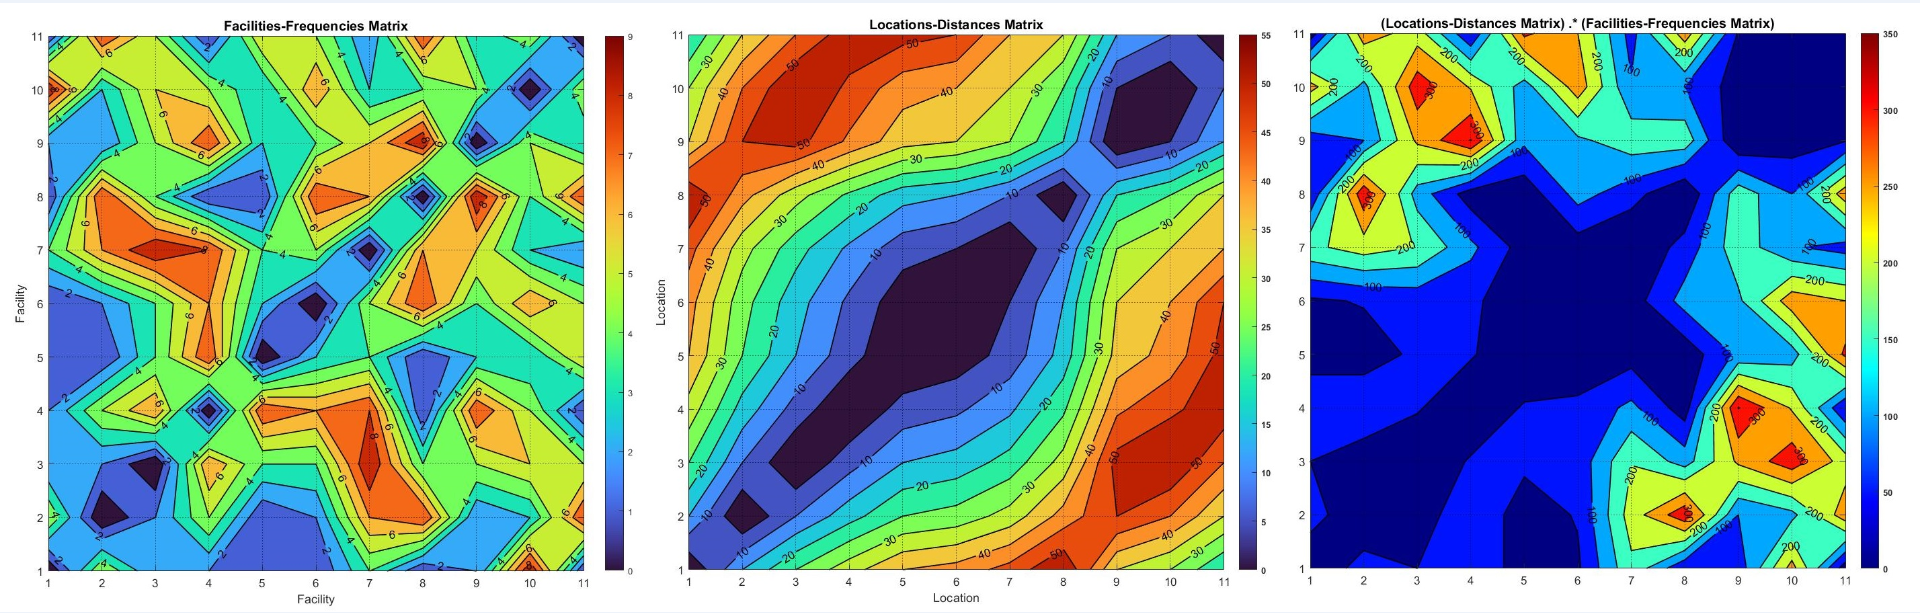

The figure above shows the symmetric contour plots of the `*facilitiesFrequenciesMatrix*` (left), `*locationsDistancesMatrix*` (middle) and the `*dot-product of both matrices`* (right). A close study of each contour plot reveals some information about the optimization problem and gives a good idea of what to expect from the optimization algorithm. The contour plots are discussed in the rest of this section. Note that *Fn* and *Ln* refer to *Facility n* and *Location n,* respectively.

- ***facilitiesFrequenciesMatrix: *** From the contour plot, there is a lot of traffic between some facilities, particulary between facility-pairs F3 & F7,  F8 & F9, and F10 & F1. Thus, it is expected that the algorithm places these facility-pairs at adjacent locations on the site.

- ***locationsDistancesMatrix: ***The contour plot shows that location-pairs L2 & L9, L3 & L10, and L4 & L11 are farthest from each other on the site. Intuitively, one can expect that only facility-pairs with little traffic between them are placed at these location-pairs and vice-versa.

- ***facilitiesFrequenciesMatrix .* facilitiesFrequenciesMatrix: ***This combined matrix and its contour plot summarizes the information contained in each matrix and shows three pairs of facility-pairs and location-pairs combinations that should be avoided. These three hotspots are result from the placement of facility-pairs with the high traffic at location-pairs with large distances. F2 & F8 should not both occupy L2 & L8 simultaneously. F3 & F10 should not both occupy L3 & L10 simultaneously. F4 & F9 should not both occupy L4 & L9 simultaneously.            

`# [>>>>>]_________________________________________________________________________________`

## 3. Constraints

The relative positions of the gates -- *Side Gate (SG)* and *Main Gate (MG)* -- are not subject to change during the allocation process and are treated as special facilities clamped on the predetermined locations. Facility 8 (S*ide Gate*) and Facility 11 (*Main Gate*) are clamped at Locations 1 and 10.

Thus, the population of chromosomes will be represented as: `[ x x x x x x x 1 x x 10 ]` where the remaining **9** blank positions '**x**'  are site locations to be assigned to the remaining **9** facilities by the optimization algorithm. 

reservedLocations = [1, 10];
specialFacilities = [8, 11];

To encode these constraints (reserved locations for special facilities) into the ACO implementation, the pheromone matrix is initialized such that reservedLocation/specialFacility index has 100% probability of being chosen by 'ants' every time. This is done as shown in the figure below, where the initial pheromone value is set to 1. 

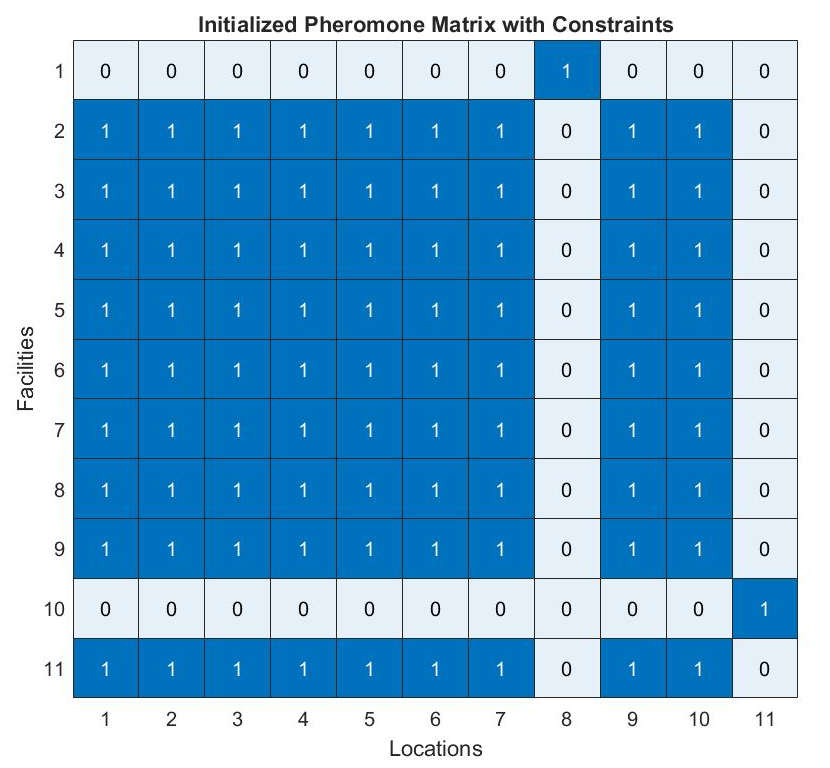

The pheromone initializations of the entire row and column containing the reservedLocation/specialFacility -- other than the reservedLocation/specialFacility index itself -- are set to zero. Thus, only one facilty can be probabilistically chosen for that locations and that same facilty will always be probabilistically assigned to the same location.

`# [>>>>>]_________________________________________________________________________________`

## 4. Optimum Solution

The optimum solution -- representIng Facility@Location-pair information -- found was:

`-----------------------------------------------------------------------------------------------`

`[ 9 11 5 6 7 2 4 1 3 8 10 ]`

`-----------------------------------------------------------------------------------------------`

`[ F1@L9 , F2@L11 , F3@L5 , F4@L6 , F5@L7 , F6@L2 , F7@L4 , F8@L1 , F9@L3 , F10@L8 , F11@L10 ]`

`-----------------------------------------------------------------------------------------------`

`[ SO@L9 , FW@L11 , LR@L5 , S1@L6 , S2@L7 , CW@L2 , RSW@L4 , SG@L1 , UCR@L3 , CBW@L8 , MG@L10 ]`

`-----------------------------------------------------------------------------------------------`

The solution was arrived at after 33 iterations with an ant colony population size of 50. The figure below shows that the pheromone matrix values (left) and normalized pheromone weights and best (optimum) solution (right) at iteration 33.

The figure shows that for F2, the only viable location was L11, even though F2 is not a reserved facility. However, for F5 and F10, multiple locations were contending for viability. Furthermore, how the pheromone weights are clustered around a small subset of the pheromone matrix shows how quickly the algorithm narrows down to optimal combinations of nodes.

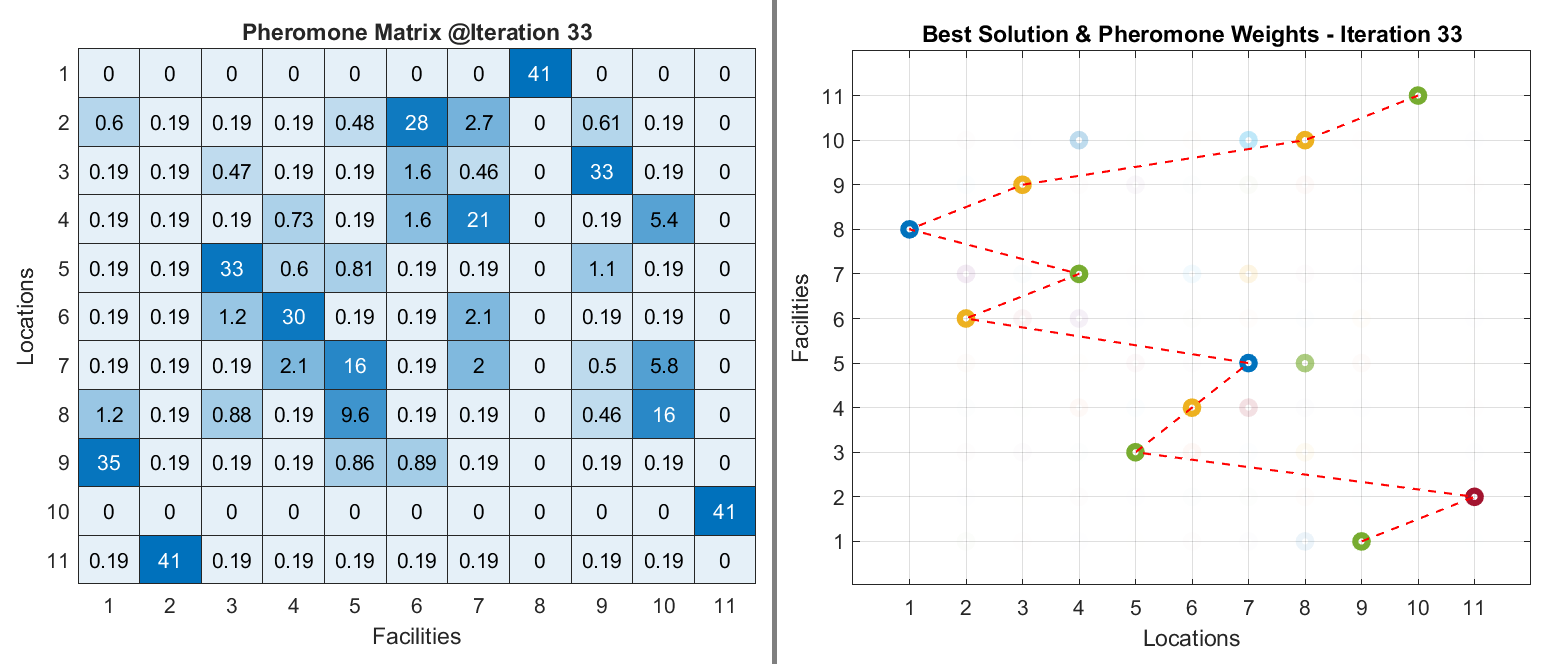

The figure below helps visualize the relative frequencies and distances of a given facility-location pair (F3/L5) with other facility-location pairs in the solution. The thickness of the lines represents the frequencies, while the length represents the distances. This helps in analyzing the optimality of the solution from a commonsensical point of view. The heuristic can be summarized as:

`...facilities with high trip frequencies between them should be placed at locations with minimal distances between them and vice-versa...`

A glance at the figure shows that the optimal solution abides by this common-sense heuristic. F3 has the highest traffic with F7 and F4, both placed at locations adjacent to L5. On the other hand, F3 has the lowest traffic with F2 and F1, thus placed further away by the algorithm.

**The same pattern will be observed if other facilities are visualized using *****`***`visualizeSolution(solution, facility)`. `**This heuristic does not hold for the so-called optimal solution presented in the source publication.**

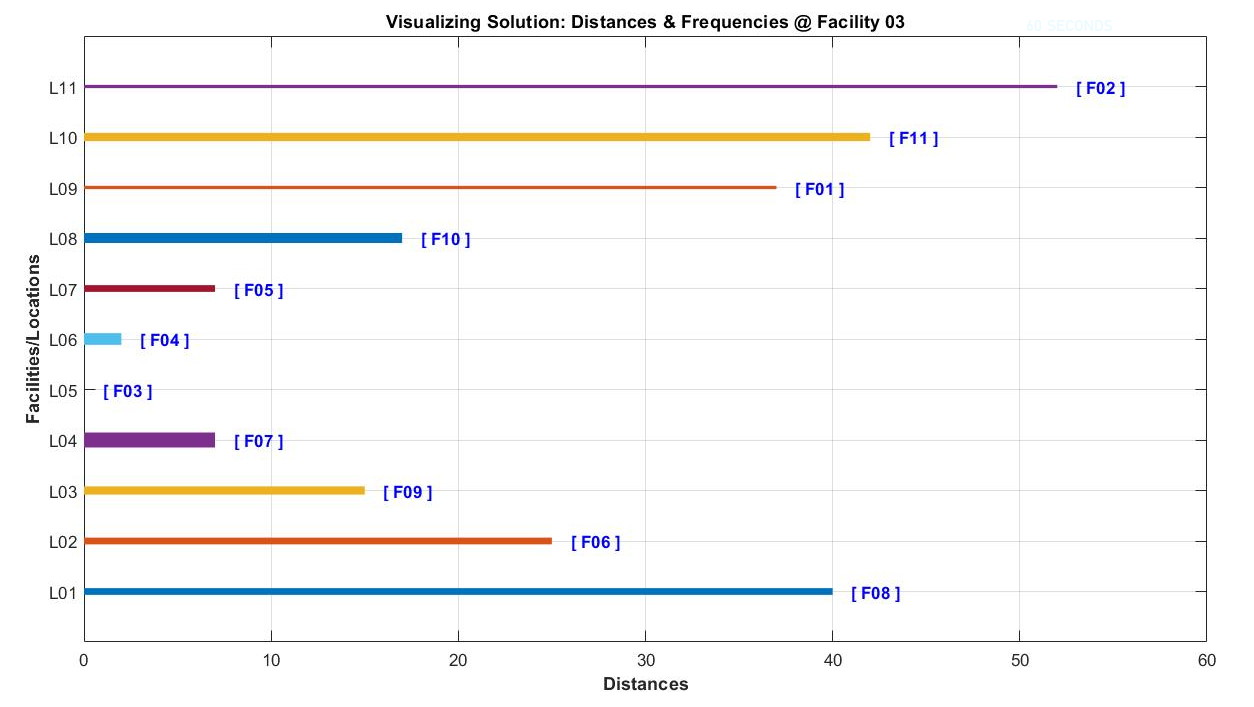

`# [>>>>>]_________________________________________________________________________________`

## 5. Code Implementation Overview

- `Initialize the algorithm hyperparameters.`

- `Initialize the pheromone matrix ``(row=locations & columns=facilities)`` with a default value of 1.`

- `Isolate reserved locations and zero out the pheromone weights for the entire row.`

- `Isolate special facilities and zero out the pheromone weights for the entire column.`

- `Set the pheromone weight for each ``(reservedLocation, specialFacility)`` to the default value (1).`

- `< START ITERATION 1 >`

- `Generate random probabilities (for each ant) and each facility's location being assigned to that location.`

- `Convert the pheromone matrice to a cumulative probabilities matrix for Roulette Wheel selection.`

- `For each ant, map out its solution using the cumulative probabilities matrix and the initially generated random probabilities.`

- `Check that for each ant's solution; no facility is assigned to two locations and vice-versa (catch bugs). Throw an error and break the loop if true.`

- `Calculate the fitness of each ant's solution.`

- `<Logging, Plotting & Printing>`

- `Check for convergence. Test if the best fitness value did not improve for some iterations. Show warning and break the loop if true.`

- `Update pheromone matrix, amplifying pheromone weights for nodes belonging to the best solution and evaporating pheromone weights for others.`

- `< END ITERATION 1 >`

- `< LOOP -- NEXT ITERATION >`

`# [>>>>>]_________________________________________________________________________________`

## 6. Code Implementation

% --- INIT ALGORITHM HYPERPARAMETERS
rng(sum(double(char("AntColonyOptimization")))) % fix the seed for random number generation
maxIterations = 100;
nIterConvergence = 10;
histFitnesses = zeros(maxIterations, nLocations+2); % best fitness | mean fitness | best solution
nPopulation = 50;
pheromoneDecayFactor = 0.05;
pheromoneScalingParameter = 1.5;
printWeights = false;


% --- INIT PHEROMONE MATRIX AND PLACE SPECIAL FACILITIES IN RESERVED LOCATIONS
pheromoneMatrix = ones(nLocations, nFacilities);

for idx = 1:length(reservedLocations)
    % clear the entire row i.e. no facilities placed at this location
    pheromoneMatrix(reservedLocations(idx),:) = 0;
    % clear the entire column i.e. this facility is not placed at any location
    pheromoneMatrix(:,specialFacilities(idx)) = 0;
    % place the special facility at its reserved location 
    pheromoneMatrix(reservedLocations(idx),specialFacilities(idx)) = 1;
end; clear idx
pheromoneMatrix

pheromoneMatrix =      0     0     0     0     0     0     0     1     0     0     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     1     1     1     1     1     1     1     0     1     1     0
     0     0     0     0     0     0     0     0     0     0     1


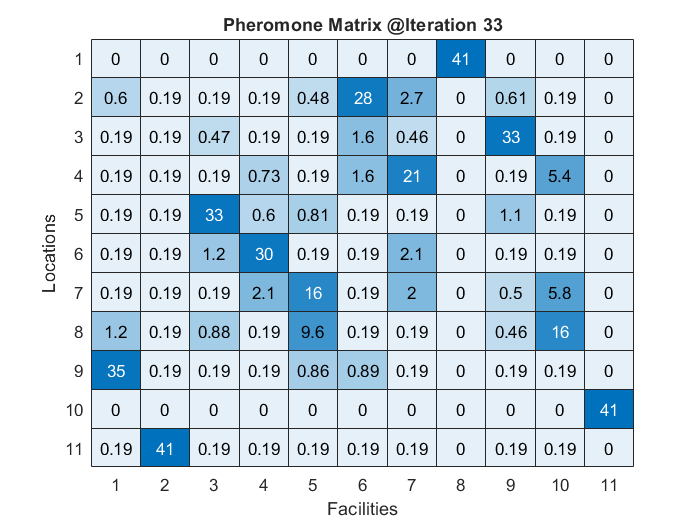

% --- START GENERATION LOOP ---
for iters = 1:maxIterations
    % --- GENERATE LOCATION-FACILITY PLACEMENT PROBABILTES FOR ALL ANTS IN POPULATION
    randLocationProbabilities = rand(nPopulation, nLocations);
    
    % --- CHOOSE THE PATH FOR EACH ANT USING ROULETTE WHEEL SELECTION
    locationsXfacilities = ones(size(randLocationProbabilities));
    facilitiesXlocations = ones(size(randLocationProbabilities));
    
    for ant = 1:nPopulation
        % create a copy of the pheromone matrix which will be updated once a facility has been assigned to a location 
        % i.e. once a facility has been assigned to a location, its pheromone values (for its column) are set to zero such that
        % there is zero probability of that same facility being assigned to another location in subsequent steps.
        tempPheromoneMatrix = pheromoneMatrix;
        
        for i = 1:nLocations
        % (re)compute the probabilities matrices to reflect any updates in the temp pheromone matrix
        [cummProbsMatrix] = l_calcProbsMatrices(tempPheromoneMatrix);
        
            for j = 1:nFacilities
                if cummProbsMatrix(i,j) > randLocationProbabilities(ant, i)
                    % TRANSLATION: facility j (column idx value) assigned to location i (column idx)
                    facilitiesXlocations(ant,j) = i;
                    % TRANSLATION: location i (column idx) contains facility j (column idx value)
                    locationsXfacilities(ant,i) = j;
                    
                    % since facility j has been assigned to a location, set column j in the temp pheromone matrix to zero 
                    % ensuring that facility j will never be selected again! because its probabilities henceforth will be zero!
                    tempPheromoneMatrix(:,j) = 0;
                    break
                end
            end
        end
    end; clear ant tempPheromoneMatrix i j locationsXfacilities cummProbsMatrix
    
    % --- TEST THAT THERE ARE NO FACILITIES ASSIGNED TO MULTIPLE LOCATIONS
    l_calcFeasibilities(facilitiesXlocations, false);
    
    % --- CALCULATE THE FITNESSES OF SOLUTIONS IN THE POPULATION
    [fitnesses, population] = l_calcObjFunction(facilitiesXlocations);
    histFitnesses(iters, :) = [fitnesses(1) mean(fitnesses) population(1,:)];
    bestSolution = population(1,:);
    
    % --- PLOT THE BEST SOLUTION AND CURRENT PHEROMONE WEIGHTS AND SAVE TO FILE
    heatmap(pheromoneMatrix, "CellLabelFormat","%0.2g", "ColorScaling","log", "ColorbarVisible","off"); 
    xlabel("Facilities"); ylabel("Locations"); title(sprintf("Pheromone Matrix @Iteration %02d", iters)); pause(1);
    if printWeights
        l_printPheromoneWeights(pheromoneMatrix, bestSolution, iters, false)
    end
        
    % --- CHECK FOR CONVERGENCE
    % terminate the algorithm if the best fitness value did not change for n iterations
    if iters > 2*nIterConvergence && length(unique(histFitnesses(iters-nIterConvergence:iters, 1))) == 1
        warning("Fitness has stagnated for %d iterations! Terminating at iteration %d!\n", nIterConvergence, iters)
        histFitnesses(iters+1:end, :) = [];
        break
    end
        
    % --- UPDATE THE PHEROMONE MATRIX
    bestNodeUpdate = pheromoneScalingParameter * (fitnesses(1)/fitnesses(end)); % add this to the current value
    otherNodesUpdate = 1-pheromoneDecayFactor; % multiply the current value by this

    for i = bestSolution
        for j = 1:nFacilities
            if j == find(bestSolution == i)
                pheromoneMatrix(i,j) = pheromoneMatrix(i,j) + bestNodeUpdate;
            else
                pheromoneMatrix(i,j) = pheromoneMatrix(i,j) * otherNodesUpdate;         
            end
        end
    end; clear i j bestNodeUpdate otherNodesUpdate bestSolution
    
    % --- END GENERATION LOOP --- 
end; clear iters randLocationProbabilities facilitiesXlocations

clear maxIterations nFacilities nIterConvergence nLocations nPopulation pheromoneDecayFactor pheromoneScalingParameter

% --- PLOTTING AND PRINTING OPTIMIZATION RESULTS
fprintf("--- Best Fitness: %d --- \n", histFitnesses(end, 1)) % best=12546

--- Best Fitness: 12546 ---

fprintf("-% d -", histFitnesses(end, 3:end)); fprintf("\n");

- 9 -- 11 -- 5 -- 6 -- 7 -- 2 -- 4 -- 1 -- 3 -- 8 -- 10 -

for i = 1:length(bestSolution)
    fprintf("Facility {%02d=%-30s} -->>-- Location {%02d} \n", i, f_Facilities(i), bestSolution(i))
end; clear i;

Facility {01=Site Office                   } -->>-- Location {09} 
Facility {02=Falsework Workshop            } -->>-- Location {11} 
Facility {03=Labor Residence               } -->>-- Location {05} 
Facility {04=Storeroom 1                   } -->>-- Location {06} 
Facility {05=Storeroom 2                   } -->>-- Location {07} 
Facility {06=Carpentry Workshop            } -->>-- Location {02} 
Facility {07=Reinforcement Steel Workshop  } -->>-- Location {04} 
Facility {08=Side Gate                     } -->>-- Location {01} 
Facility {09=Utilities Control Room        } -->>-- Location {03} 
Facility {10=Concrete Batch Workshop       } -->>-- Location {08} 
Facility {11=Main Gate                     } -->>-- Location {10} 


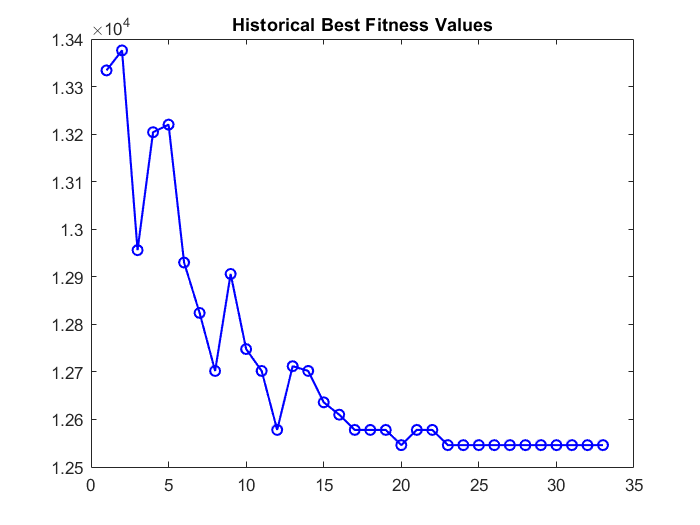

plot(histFitnesses(:, 1), 'b-o', "LineWidth",1.25); title("Historical Best Fitness Values");

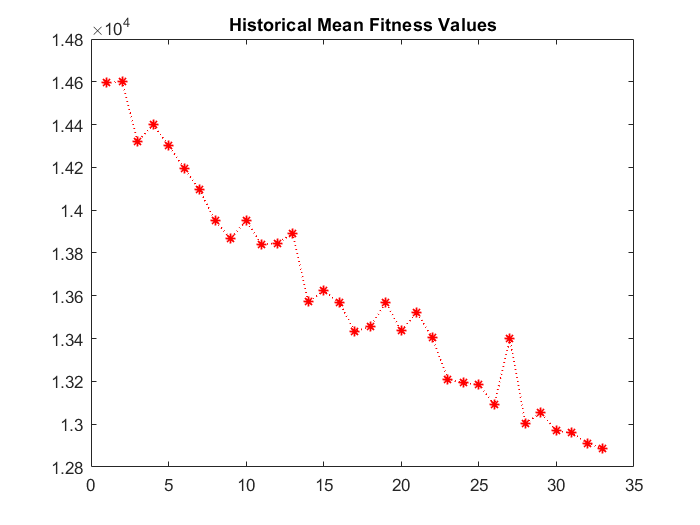

plot(histFitnesses(:, 2), 'r:*', "LineWidth",1); title("Historical Mean Fitness Values");

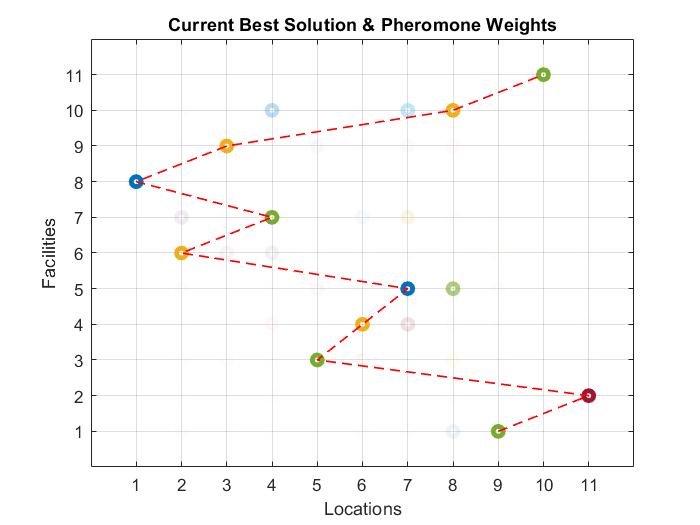

l_printPheromoneWeights(pheromoneMatrix, histFitnesses(end, 3:end));

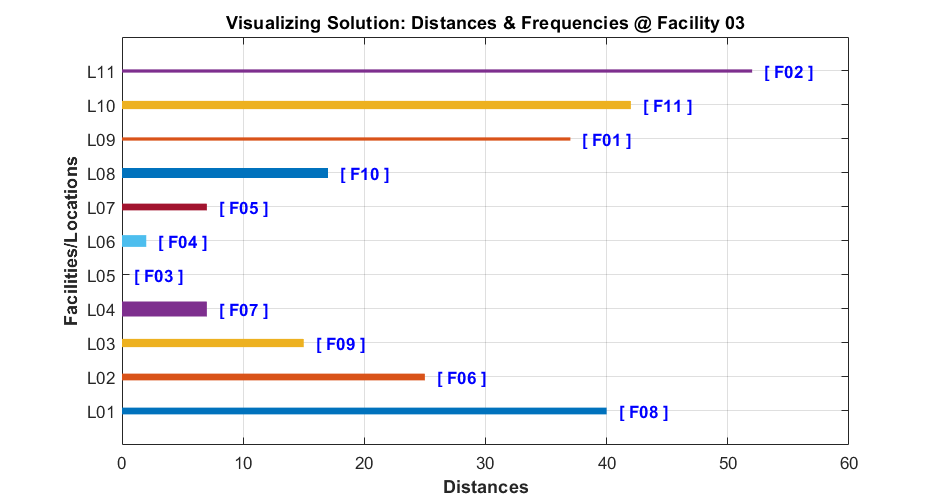

l_visualizeSolution(histFitnesses(end, 3:end), 3);

`# [>>>>>]_________________________________________________________________________________`

## 7. Local (Helper) Functions

### `>>> l_calcFeasibilities`

function l_calcFeasibilities(solutionsMatrix, verbose)
[nPopulation, nVariables] = size(solutionsMatrix);
nUniques = zeros(1, nPopulation);

for i = 1:nPopulation
    nUniques(i) = length(unique(solutionsMatrix(i,:)));
end

feasibilityCheck = nUniques == nVariables;
if sum(feasibilityCheck) ~= nPopulation
    error("There are INVALID solutions in the population!")
else
    if verbose
        disp("All solutions in the population are VALID!")
    end
end

end

### `>>> l_calcObjFunction`

function [popFitnesses, sortedPopulation] = l_calcObjFunction(population)
global facilitiesFrequenciesMatrix locationsDistancesMatrix
[nLocations, nFacilities] = size(facilitiesFrequenciesMatrix);
[nPopulation, ~] = size(population);
popFitnesses = zeros(nPopulation, 1);

for idx = 1:nPopulation
    chrmsm = population(idx,:);
    distXfreq = zeros(nLocations, nFacilities);
    for i = 1:nLocations
        for j = 1:nFacilities
            dist = locationsDistancesMatrix(chrmsm(i),chrmsm(j));
            freq = facilitiesFrequenciesMatrix(i,j);
            distXfreq(i,j) = dist*freq;
        end
    end
    popFitnesses(idx) = sum(sum(distXfreq));
end

if nPopulation > 1
    temp = [population, popFitnesses];
    temp = sortrows(temp, nLocations+1);
    sortedPopulation = temp(:, 1:nLocations); 
    popFitnesses = temp(:, nLocations+1);
end

end

### `>>> l_calcProbsMatrices`

function [cummProbsMatrix] = l_calcProbsMatrices(pheromoneMatrix)
[nLocations, nFacilities] = size(pheromoneMatrix);

probsMatrix = zeros(size(pheromoneMatrix));
for i = 1:nLocations
    for j = 1:nFacilities
        probsMatrix(i,j) = pheromoneMatrix(i,j) / sum(pheromoneMatrix(i,:));
    end
end

cummProbsMatrix = probsMatrix;
for i = 2:nLocations
    for j = 2: nFacilities
        cummProbsMatrix(i,j) = cummProbsMatrix(i,j-1) + cummProbsMatrix(i,j);
    end
end

end

### `>>> l_printPheromoneWeights`

function l_printPheromoneWeights(pheromoneMatrix, bestSolution, iters, display)

if nargin < 3
    iters = 0;
    display = true;
end
    
normPheromoneMatrix = zeros(size(pheromoneMatrix));
[nLocations, nFacilities] = size(pheromoneMatrix);

for i = 1:nLocations
    normPheromoneMatrix(i,:) = pheromoneMatrix(i,:) - min(pheromoneMatrix(i,:));
    normPheromoneMatrix(i,:) = normPheromoneMatrix(i,:) / max(normPheromoneMatrix(i,:));
end

if not(display)
    figure('visible', 'off');
end

for i = 1:nLocations
    for j = 1:nFacilities
        scatter(i, j, 'o', 'MarkerEdgeAlpha', normPheromoneMatrix(i,j), "LineWidth", 3);
        hold on; 
    end
end

grid on; box on;
axis([0 nFacilities+1 0 nLocations+1]); 
xticks([1:1:nFacilities]); yticks([1:1:nLocations]);
xlabel("Locations"); ylabel("Facilities");

if not(display)
    title(sprintf("Best Solution & Pheromone Weights - Iteration %02d", iters));
else
    title("Current Best Solution & Pheromone Weights");
end

plot(bestSolution, [1:1:length(bestSolution)], "r--", "LineWidth",1);
hold off;

if not(display)
    print(sprintf('Pheromone_Matrix_Weights_%02d', iters), "-dpng")
end

end

### `>>> l_visualizeSolution`

function l_visualizeSolution(solution, facility)
global facilitiesFrequenciesMatrix locationsDistancesMatrix
n_vals = length(solution);
y_vals = zeros(n_vals);
y_labels = [];
y_textx = [];
x_dists = zeros(n_vals);
t_freqs = zeros(n_vals);

for i = 1:length(solution)
    y_vals(i) = i;
    x_dists(i) = locationsDistancesMatrix(solution(facility), i);
    
    if i == facility
        t_freqs(solution(i)) = 1;
    else
        t_freqs(solution(i)) = facilitiesFrequenciesMatrix(facility, i);
    end
    
    y_labels{solution(i)} = sprintf("L%02d", solution(i));
    y_texts{solution(i)} = sprintf("[ F%02d ]", i);
end

for i = 1:length(solution)
    plot([0, x_dists(i)], [y_vals(i), y_vals(i)], 'LineWidth', t_freqs(i));
    text(x_dists(i) + 1, y_vals(i), y_texts(i), 'FontWeight', "bold", 'Color', "b");
    hold on;
end

grid("on");
ylim([0, 12]); yticks([1:1:11]);
yticklabels(y_labels); 
ylabel("Facilities/Locations", 'FontWeight', "bold"); 
xlabel("Distances", 'FontWeight', "bold"); 
title(sprintf("Visualizing Solution: Distances & Frequencies @ Facility %02d", facility));
set(gcf, 'Position', [90 260 750 400]);

hold off;

end

## __end__